**Taller 2**

**Zelnik1**

clc;
clear all;
rng(0);
datos = importdata("zenik1.txt");
X = datos(:,1:2);

% Diagrama de codo kmeans
fprintf("kmeans");

kmeans

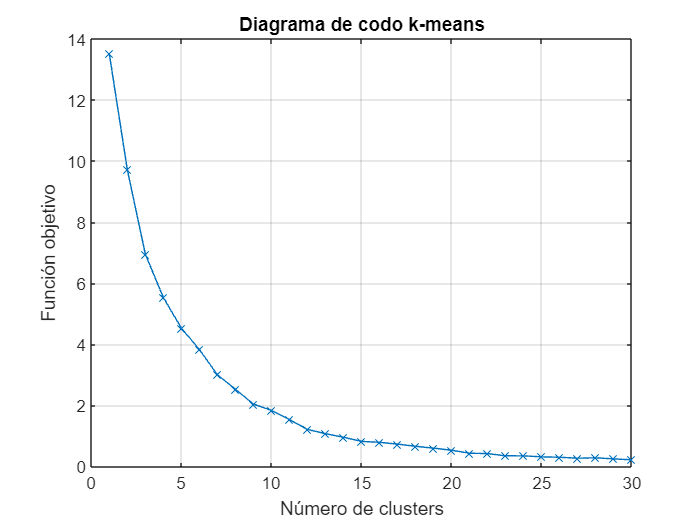

n = 30;
for i =1:n
    [idx, C, SumD] = kmeans(X,i);
    J(i) = sum(SumD);
    K(i) = i;
end

figure;
plot(K, J,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo");
title("Diagrama de codo k-means");

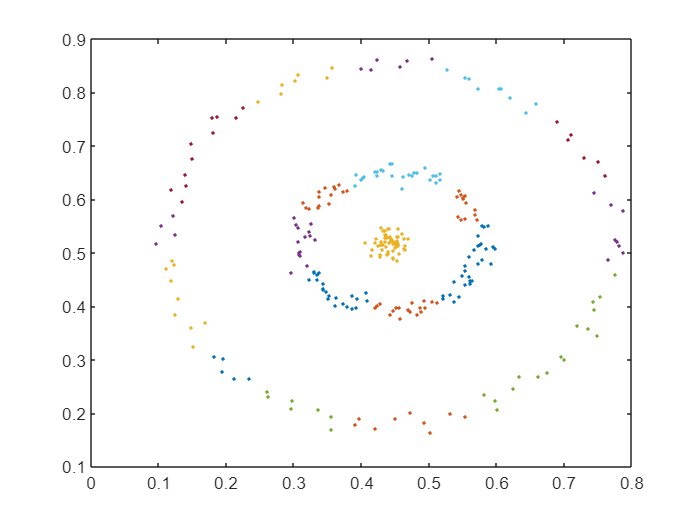


k=25;
idx = kmeans(X,k);

figure;
for i=1:k
plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)]);
hold on;
end


fprintf("kmeans");

kmeans

[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X,idx)

SSW = 0.0268

SSB = 0.1703

WB = 3.9413

SIL = 0.7286


fprintf("kmedoids");

kmedoids

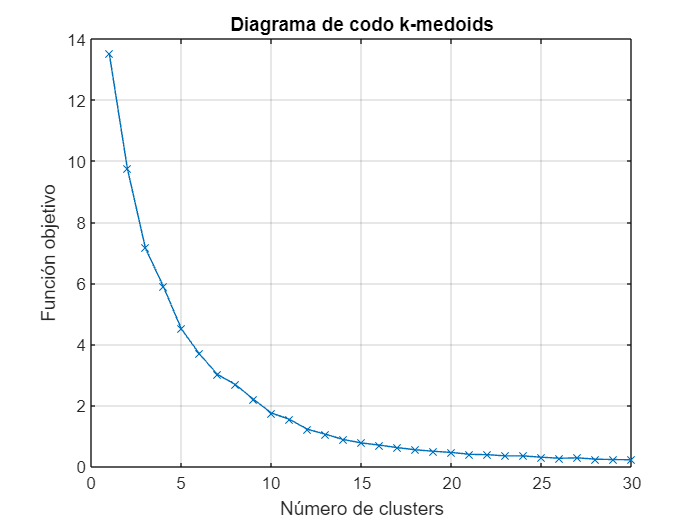


% Diagrama de codo kmedoids
for i =1:n
    [idx, C, SumD] = kmedoids(X,i);
    J(i) = sum(SumD);
    K(i) = i;
end

figure;
plot(K, J,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo");
title("Diagrama de codo k-medoids");

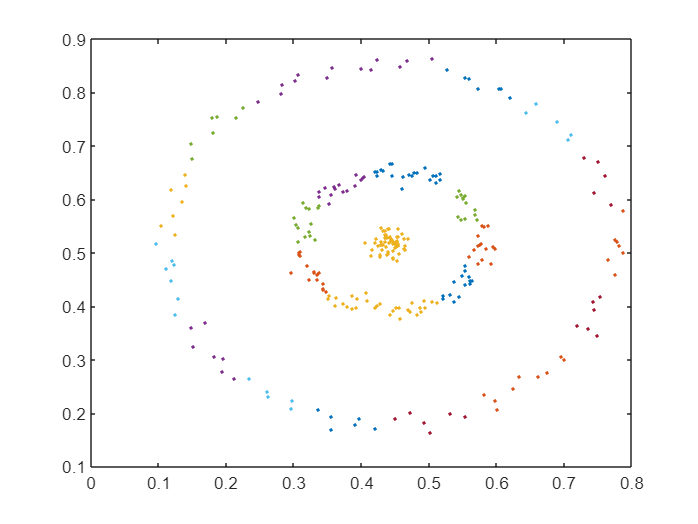


k=25;
idx = kmedoids(X,k);

figure;
for i=1:k
plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)]);
hold on;
end


[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X(:,1:2),idx)

SSW = 0.0262

SSB = 0.1704

WB = 3.8480

SIL = 0.7183


fprintf("DBSCAN");

DBSCAN


ep = clusterDBSCAN.estimateEpsilon(X,2,10)

ep = 0.0255

idx = dbscan(X,ep,10);
k1 = max(idx);
idx(idx==-1)= k1+1;
idx(idx==0)= k1+2;
k0 = min(idx)

k0 = 1

k1 = max(idx)

k1 = 5

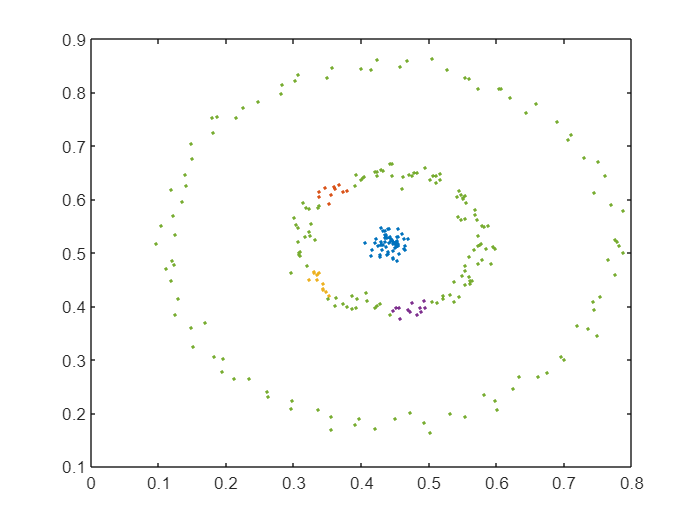


figure;
for i=k0:k1
plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)]);
hold on;
end


[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X(:,1:2),idx)

SSW = 0.1624

SSB = 0.0222

WB = 36.6551

SIL = -0.2158